# Hartree-Fock Method

## Slater Determinant

Electrons are fermions and hence, they must obey the **antisymmetry principle **stating that a total wavefunction describing both coordinate and spin parts should be antisymmetric (i.e. change sign) with respect to exchanging all quantum numbers of any two electrons. In the following when used as an argument of wave function denoted by $\psi$ (in the case of single-electron as well as many-electron wave function) the variable ${\bf r}$ will include both the coordinate and spin variables. For the two-electron wave function antisymmetry principle means:


$$\begin{array}{cc}\psi\left(\mathbf{r}_2,\mathbf{r}_1\right) = - \psi\left(\mathbf{r}_1,\mathbf{r}_2\right).& \qquad (1)\\ \end{array}$$


$N$-electron wave functions that satisfy antisymmetry principle and are constructed out of the single-particle wave functions are conveniently represented as **Slater determinants**,


$$\begin{array}{cc}\psi\left(\mathbf{r}_1, \mathbf{r}_2, \ldots \mathbf{r}_N\right)=\frac{1}{\sqrt{N !}} \left|\begin{array}{cccccccccccccc}\psi_1\left(\mathbf{r}_1\right) & \psi_2\left(\mathbf{r}_1\right) & \cdots & \psi_N\left(\mathbf{r}_1\right) \\\psi_1\left(\mathbf{r}_2\right) & \psi_2\left(\mathbf{r}_2\right) & \cdots & \psi_N\left(\mathbf{r}_2\right) \\\vdots & \vdots & \ddots & \vdots \\\psi_1\left(\mathbf{r}_N\right) & \psi_2\left(\mathbf{r}_N\right) & \cdots & \psi_N\left(\mathbf{r}_N\right)\\ \end{array}\right|,& \qquad (2)\\ \end{array}$$


where $\psi_m(\mathbf{r}_j)$ are orthonormalized spin-orbitals that include both coordinate and spin parts of the single-particle wave function. Explicitly, separating space and spin variables: $\psi_m(\mathbf{r}_j)=\phi_m(\mathbf{r}_j) |\sigma_m\rangle_j$, where $\phi_m(\bf{r})$ is coordinate wave function and spin state of $j$-th electron in spin-orbital state $\psi_m(\mathbf{r}_j)$ is $|\sigma_m \rangle_j$ with $\sigma_m$ restricted to two possible values $\pm 1/2$ or equivalently $\uparrow$ and $\downarrow$, with $_j\langle \sigma_{n} |\sigma_m \rangle_j =\delta_{\sigma_m,\sigma_{n}}$. 

 If we define by $P_n$ the permutation operator of the electron indices and let $p_n$ be either 0 or 1 depending on the parity of the permutation, Slater determinant state given in Eq. (2) can be written as:


$$\begin{array}{cc}\psi\left(\mathbf{r}_1, \mathbf{r}_2, \ldots \mathbf{r}_N\right)=\frac{1}{\sqrt{N !}} \sum_{n=1}^{N !}(-1)^{p_{n}} P_{n}\left\{\psi_{1}(\mathbf{r}_1) \psi_{2}(\mathbf{r}_2) \ldots \psi_{N}(\mathbf{r}_N)\right\}.& \qquad (3)\\ \end{array}$$


In case of 2 electrons, for the total wave function of helium atom's electrons, we have the following representation in spin-orbitals


$$\begin{array}{cc}\psi\left(\mathbf{r}_1,\mathbf{r}_2\right)=\frac{1}{\sqrt{2}}\left[\psi_1\left(\mathbf{r}_1\right) \psi_2\left(\mathbf{r}_2\right)-\psi_2\left(\mathbf{r}_1\right) \psi_1\left(\mathbf{r}_2\right)\right],& \qquad (4)\\ \end{array}$$


where $\psi_1(\mathbf{r})$ and $\psi_2(\mathbf{r})$ must be different spin-orbitals, otherwise wave function given in Eq. (4) will vanish. We can have for example: $\psi_{1}\left(\mathbf{r}_1\right)=\phi_{1s}({\bf r_1}) |\uparrow\rangle_1$ and $\psi_2\left(\mathbf{r}_2\right)=\phi_{1s}({\bf r_2}) |\downarrow\rangle_2$. In this case Eq. (4) will describe a configuration where two electrons occupy same $1s$ spatial orbital and form spin-singlet state: $\psi\left(\mathbf{r}_1,\mathbf{r}_2\right)=\frac {\phi_{1s} ({\bf r}_1)\phi_{1s} ({\bf r}_2)}{\sqrt{2}} \Big[|\uparrow \rangle_1 |\downarrow \rangle_2-|\downarrow \rangle_1 |\uparrow \rangle_2 \Big]$.

We will work in the [Hartree system of atomic units](https://en.wikipedia.org/wiki/Hartree_atomic_units) (with $\hbar= m_e=e=1$). In atomic units the distance ($r$) is measured in units of Bohr radius ($a_0$), and energy - in units of Hartree energy $E_h$.

Our task is to compute $\langle\Psi|\hat H| \Psi\rangle$, where $\langle \mathbf{r_1},\mathbf{r_2},\cdots,\mathbf{r_N}|\Psi\rangle$ has a Slater determinant form given in Eq. (2). The Hamiltonian of $N$-electron system with $N_n\ge 1$ nuclear cores fixed at equilibrium positions $\mathbf{R}_I$ and nuclear charges $Z_1$, $Z_2$,..., $Z_{N_n}$ is:


$$\begin{array}{cc}\hat{H} =\hat{T}+\hat{V}_{e n}+\hat{V}_{e e}  =-\frac{1}{2} \sum_{i=1}^{N} \nabla_{i}^{2}-\sum_{i=1}^{N} \sum_{I=1}^{N_{n}} \frac{Z_{I}}{\left|\mathbf{r}_{i}-\mathbf{R}_{I}\right|}+ \sum_{i=1}^{N} \sum_{j=1 (j > i)}^{N} \frac{1}{\mid \mathbf{r}_{i}-\mathbf{r}_{j}  \mid}   \\ =\sum_{i=1}^{N} \hat H_{1}(i)+\sum_{i=1}^{N} \sum_{j>i}^{N} \hat H_{2}(i, j),& \qquad (5)\\ \end{array}$$


where $\sum_i\hat H_1(i)$ is the one-electron operator, sum of kinetic energy $\hat T$ and electron-nucleus Coulomb interaction potential $\hat V_{en}$ terms. $\sum_{j>i}\hat H_2(i,j)$ is the two-electron operator, electron-electron Coulomb interaction potential $\hat V_{ee}$. To shorten expressions, a single-particle state will be expressed in bra–ket notation $\langle\mathbf{r}|m\rangle=\psi_m\left(\mathbf{r}\right)$. By using the orthonormalization of $\psi_m(\mathbf{r})$ functions and the indistinguishability of electrons, we can use [Slater-Condon rules](https://en.wikipedia.org/wiki/Slater%E2%80%93Condon_rules) to simplify


$$\begin{array}{cc}\sum_{i=1}^{N}\left\langle\Psi\left|\hat H_{1}(i)\right| \Psi\right\rangle= \sum_{i=1}^{N}\frac{1}{N} \sum_{m=1}^{N}\left\langle m\left|\hat H_{1}(i)\right| m\right\rangle = \sum_{m=1}^{N}\left\langle m\left|\hat H_{1}\right| m\right\rangle.& \qquad (6)\\ \end{array}$$


Similarly, we can simplify the two-electron part of the Hamiltonian as (recalling that in the system of $N$ electrons there are $N(N-1)/2$ distinct pairs of electrons)


$$\begin{array}{cc}\sum_{i=1}^{N} \sum_{j>i}^{N} \left\langle\Psi\left| \hat H_{2}(i,j)\right| \Psi\right\rangle =\frac{N(N-1)}{2}\left\langle\Psi\left|\hat H_{2}(1,2)\right| \Psi\right\rangle = \frac{1}{2} \sum_{m=1}^{N} \sum_{n=1}^{N} \Big[\left\langle m n\left|\hat H_{2}\right| m n\right\rangle-\left\langle m n\left|\hat H_{2}\right| n m\right\rangle\Big].& \qquad (7)\\ \end{array}$$


At the end of the live script we leave as an exercise derivation of Eqs. (6) and (7) .

See Exercise 1 in live script *From Many-Body Wave Function Description to DFT,* where we represent  $\frac{1}{2} \sum_{m=1}^{N} \sum_{n=1}^{N} \Big[\left\langle m n\left|\hat H_{2}\right| m n\right\rangle-\left\langle m n\left|\hat H_{2}\right| n m\right\rangle\Big]$ with the help of two-electron density  $\displaystyle \int \int  \frac{\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|} d \mathbf{r} d \mathbf{r}^{\prime}$, where $d\mathbf{r}\equiv d^3\mathbf{r}$ and $\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)= \rho(\mathbf{r}) \rho(\mathbf{r}^{\prime})/2+\Delta \rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)$. Single-electron density in Slater determinant state, as well as in Hartree product state $\psi_{\mathrm{Hartree}}\left(\mathbf{r}_1, \mathbf{r}_2, \ldots \mathbf{r}_N\right)=\psi_{1}(\mathbf{r}_1) \psi_{2}(\mathbf{r}_2) \ldots \psi_{N}(\mathbf{r}_N)$, is $\rho(\mathbf{r})=\sum_{m=1}^N \psi_m^*(\mathbf{r})\psi_m(\mathbf{r})=\sum_{m=1}^N \phi_m^*(\mathbf{r})\phi_m(\mathbf{r})$ and we have, 


$$\frac{1}{2} \sum_{n,m=1}^{N} \left\langle m n\left|\hat H_{2}\right| m n\right\rangle =\frac{1}{2}\int \int  \frac{\rho(\mathbf{r})\rho( \mathbf{r'})}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|} d \mathbf{r} d \mathbf{r}^{\prime} \qquad(7a)$$


and


$$-\frac{1}{2} \sum_{m,n=1}^{N} \left\langle m n\left|\hat H_{2}\right| n m\right\rangle=\int \int  \frac{\Delta\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|} d \mathbf{r} d \mathbf{r}^{\prime}. \qquad(7b)$$


The term $\Delta \rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)$ in Eq. (7b) subtracts the unphysical self-interaction of electrons that is included in the expression Eq. (7a) (self-interaction terms like $|\phi_m(\mathbf{r})|^2|\phi_m(\mathbf{r'})|^2$)  and in case $\langle \mathbf{r_1},\mathbf{r_2},\cdots\mathbf{r_N}|\Psi\rangle$ has a Slater determinant form given in Eq. (2), $\Delta \rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)$ also includes exchange interaction between the same spin electrons. 


$$\Delta\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)=  - \frac{1}{2}\sum_{n,m=1}^N\sum^{\frac{1}{2}}_{\sigma_m, \sigma_n=-\frac{1}{2}} \delta_{\sigma_m,  \sigma_n}  \phi^*_m (\mathbf{r})  \phi_m (\mathbf{r'})    \phi^*_n (\mathbf{r'})  \phi_n (\mathbf{r}).$$


Note, self-interaction terms are those corresponding to $m=n$.

For Hartree product state (no antisymmetrization) we have:


$$\rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)= \rho(\mathbf{r}) \rho(\mathbf{r}^{\prime})/2 - \sum_{m=1}^N | \phi_m (\mathbf{r})|^2 | \phi_m (\mathbf{r'})|^2/2.$$


Hence in the case of Hartree product state, $\Delta \rho^{(2)}\left(\mathbf{r}, \mathbf{r}^{\prime}\right)$ only subtracts self-interaction terms from $\rho(\mathbf{r}) \rho(\mathbf{r}^{\prime})/2$ and no exchange interaction is present.

## Hartree-Fock Method 

To find the minimal energy of the electron system described by Hamiltonian Eq. (5) in the states described by the single Slater determinant of the form given in Eq. (2), we need to minimize the Lagrange function  ${\cal L} = \langle\Psi|\hat H| \Psi\rangle-\sum_{m=1}^{N}\sum_{n=1}^{N} \epsilon_{m,n }\left(\langle m \mid n\rangle-\delta_{m,n}\right)$, with the Lagrange multiplier matrix $\epsilon_{m,n}$ implementing orthonormalization of single-particle states. Choosing the basis such that $\langle m \mid n\rangle = 0$ for $m\neq n$ , i.e. single-particle wave functions are orthogonal to each other, the Lagrange multiplier matrix becomes diagonal: $\epsilon_{m,n}=\delta_{m,n}\epsilon_m$. See [here](https://www.azchemie.com/Hartree_Fock.pdf) justification of using diagonal Lagrange miltiplier matrix for enforcing orthonormalization of single-particle orbitals without loss of generality. Hence, it is enough to impose unit normalization of $\phi_m(\mathbf{r})$ by $\partial {\cal L} / \partial \epsilon_m=0$.

Putting to zero variational derivative of the Lagrange function with respect to $\phi^*_m(\mathbf{r})$ 


$$\begin{array}{cc}   \frac{\delta}{ \delta \phi^*_m(\mathbf{r})} \Big[  \langle\Psi| \hat H| \Psi\rangle-\sum_{m=1}^{N} \epsilon_{m }\left(\langle m \mid m\rangle-1\right) \Big]=0& \qquad (8)\\ \end{array}$$


gives us for $m=1,2,\cdots, N$


$$\begin{array}{cc} \hat f \left(\mathbf {r}\right) \phi_{m}\left(\mathbf{r}\right) =\epsilon_{m} \phi_{m}\left(\mathbf{r}\right),& \qquad (9)\\ \end{array}$$


where


$$\begin{array}{cc}\hat f\left(\mathbf{r}_1\right) \phi_{m}\left(\mathbf{r}_1\right) =\hat H_{1}\phi_{m}\left(\mathbf{r}_1\right) +\sum_{n=1}^{N} \int  \frac{1}{r_{12}}\left|\phi_{n}\left(\mathbf{r}_2\right)\right|^{2}\phi_{m}\left(\mathbf{r}_1\right)d \mathbf{r}_2 -\sum_{n=1}^{N} \delta_{\sigma_n, \sigma_m}\int  \phi_{n}^{*}\left(\mathbf{r}_2\right) \frac{1}{r_{12}} \phi_{m}\left(\mathbf{r}_2\right) \phi_{n}\left(\mathbf{r}_1\right)d \mathbf{r}_2.& \qquad (10)\\ \end{array}$$


Operator $\hat f$ is called the **Fock operator**. Note, the last term in the right hand side of Eq. (10) does not have a classical analogue and is called exchange term. It only exists between the electrons of the same spin component $\sigma_n=\sigma_m$. In the following we will study systems in the closed-shell configurations (each orbital occupied by spin-up and spin-down electrons and $\rho_{\uparrow}(\mathbf{r})=\rho_{\downarrow}(\mathbf{r})=\rho(\mathbf{r})/2$), hence with $N$ even. In the following, in such situations it is convenient to redefine indexing of single-electron coordinate wave functions as compared to Eq. (10): $\phi_1=\phi_2 \to \phi_1, \phi_3=\phi_4 \to \phi_2,..., \phi_{N-1}=\phi_N\to \phi_{N/2}$. To form the many-particle ground state, we can focus on the $\frac{N}{2}$ lowest-energy spatial states (indexed according to new convention) $\left\{\phi_{n} \mid n=1,2, \ldots, N / 2\right\}$, and then doubly occupy each with electrons of opposite spin. Hartree-Fock minimal energy will be $E^{HF}_0=2\sum_{n=1}^{N/2} \epsilon_n$ (see Exercise 2). We will illustrate this in details on example of $N=4$. For $N=4$ we write out Slater determinant many-body state by separating explicitly single-particle wave functions into the coordinate and spin parts, first with old indexing convention:


$$\begin{array}{cc}\psi\left(\mathbf{r}_1, \mathbf{r}_2 ,\mathbf{r}_3, \mathbf{r}_4 \right)=\frac{1}{\sqrt{4 !}} \left|\begin{array}{cccccccccccccc}\phi_1\left(\mathbf{r}_1\right)  |\uparrow \rangle_1& \phi_2 \left(\mathbf{r}_1\right) |\downarrow \rangle_1 & \phi_3 \left(\mathbf{r}_1\right) |\uparrow \rangle_1 &   \phi_4 \left(\mathbf{r}_1\right) |\downarrow\rangle_1     \\\phi_1\left(\mathbf{r}_2\right)  |\uparrow\rangle_2& \phi_2 \left(\mathbf{r}_2\right) |\downarrow \rangle_2 & \phi_3 \left(\mathbf{r}_2\right) |\uparrow \rangle_2 &   \phi_4 \left(\mathbf{r}_2\right) |\downarrow \rangle_2  \\\phi_1\left(\mathbf{r}_3\right)  |\uparrow \rangle_3& \phi_2 \left(\mathbf{r}_3\right) |\downarrow \rangle_3 & \phi_3 \left(\mathbf{r}_3\right) |\uparrow \rangle_3 &   \phi_4 \left(\mathbf{r}_3\right) |\downarrow \rangle_3     \\\phi_1\left(\mathbf{r}_4\right)  |\uparrow \rangle_4& \phi_2 \left(\mathbf{r}_4\right) |\downarrow \rangle_4 & \phi_3 \left(\mathbf{r}_4\right) |\uparrow \rangle_4 &   \phi_4 \left(\mathbf{r}_4\right) |\downarrow \rangle_4 \\\end{array}\right|. & \\ \end{array}$$


In case $\phi_1=\phi_2$ are $1s$ orbitals and $\phi_3=\phi_4$ are $2s$ orbitals, $\psi$ can describe beryllium ground state with closed-shells: $1s^22s^2$. We write out such closed-shell wave function, by reindexing orbitals $\phi_1=\phi_2 \to \phi_1$ and $\phi_3=\phi_4\to \phi_2$: 


$$\begin{array}{cc}\psi\left(\mathbf{r}_1, \mathbf{r}_2 ,\mathbf{r}_3, \mathbf{r}_4 \right)=\frac{1}{\sqrt{4 !}} \left|\begin{array}{cccccccccccccc}\phi_1\left(\mathbf{r}_1\right)  |\uparrow_1\rangle& \phi_1 \left(\mathbf{r}_1\right) |\downarrow \rangle_1 & \phi_2 \left(\mathbf{r}_1\right) |\uparrow \rangle_1 &   \phi_2 \left(\mathbf{r}_1\right) |\downarrow \rangle_1     \\\phi_1\left(\mathbf{r}_2\right)  |\uparrow \rangle_2& \phi_1 \left(\mathbf{r}_2\right) |\downarrow \rangle_2 & \phi_2 \left(\mathbf{r}_2\right) |\uparrow \rangle_2 &   \phi_2 \left(\mathbf{r}_2\right) |\downarrow \rangle_2  \\\phi_1\left(\mathbf{r}_3\right)  |\uparrow \rangle_3& \phi_1 \left(\mathbf{r}_3\right) |\downarrow \rangle_3 & \phi_2 \left(\mathbf{r}_3\right) |\uparrow \rangle_3 &   \phi_2 \left(\mathbf{r}_3\right) |\downarrow \rangle_3     \\\phi_1\left(\mathbf{r}_4\right)  |\uparrow \rangle_4& \phi_1 \left(\mathbf{r}_4\right) |\downarrow \rangle_4 & \phi_2 \left(\mathbf{r}_4\right) |\uparrow\rangle_4 &   \phi_2 \left(\mathbf{r}_4\right) |\downarrow\rangle_4 \\\end{array}\right|. \qquad(11)& \\ \end{array}$$


Plugging such closed-shell wave function but now for $N$ electrons in Eq. (10) yields for $m=1,2,...,N/2$


$$\begin{array}{cc}\hat f\left(\mathbf{r}_1\right) \phi_{m}\left(\mathbf{r}_1\right) =\hat H_{1}\phi_{m}\left(\mathbf{r}_1\right) +\sum_{n=1}^{N/2} \left\{ 2\int \frac{1}{r_{12}}\left|\phi_{n}\left(\mathbf{r}_2\right)\right|^{2}\phi_{m}\left(\mathbf{r}_1\right) d \mathbf{r}_2 - \int  \phi_{n}^{*}\left(\mathbf{r}_2\right) \frac{1}{r_{12}} \phi_{m}\left(\mathbf{r}_2\right) \phi_{n}\left(\mathbf{r}_1\right)d \mathbf{r}_2 \right\}.& \qquad (12)\\ \end{array}$$


Instead of solving the system of Hartree-Fock Eqs. (9) directly, it is much simpler to expand single-particle states in some *basis functions*. In that case we will be optimizing only for expansion coefficients and **reduce the problem of finding the unknown single-particle wave functions to finding the unknown expansion coefficient**s. Suppose that $\left\{\chi_{\mu}\right\}$ represents a set of (non-orthonormal) basis functions in the Hilbert space of square-integrable functions. In practice, we must choose some $N_{\chi}$-element subset of this basis for a numerical implementation. We can then approximate the $i$ -th spatial wave function by a linear combination


$$\begin{array}{cc}\phi_{i}=\sum_{\mu=1}^{N_{\chi}} C_{\mu i} \chi_{\mu} \quad i=1,2, \ldots,\left(N_{\chi} \geq \frac{N}{2}\right).& \qquad (13)\\ \end{array}$$


The above expression would be exact if the truncated basis set $\left\{\chi_{\mu} \mid \mu=1,2, \ldots, N_{\chi}\right\}$ were complete. However, in practice, there are a few basis functions chosen, and expansion in Eq. (13) is an approximation, accuracy of which depends on the luck of the chosen basis functions. Using expansion in Eq. (13), Eq. (9) leads to:


$$\begin{array}{cc}\hat f\left(\mathbf{r}\right) \sum_{\nu=1}^{N_{\chi}} C_{\nu m} \chi_{\nu}\left(\mathbf{r}\right)=\epsilon_{m} \sum_{\nu=1}^{N_{\chi}} C_{\nu m} \chi_{\nu}\left(\mathbf{r}\right).& \qquad (14)\\ \end{array}$$


We then multiply by $\chi_{\mu}^{*}\left(\mathbf{r}\right)$ both sides of Eq. (14) and integrate over space, to obtain


$$\begin{array}{cc}\sum_{\nu=1}^{N_{\chi}}\left\{\int  \chi_{\mu}^{*}\left(\mathbf{r}\right) f\left(\mathbf{r}\right) \chi_{\nu}\left(\mathbf{r}\right) d \mathbf{r}\right\} C_{\nu m}=\epsilon_{m} \sum_{\nu=1}^{N_{\chi}}\left\{\int \chi_{\mu}^{*}\left(\mathbf{r}\right) \chi_{\nu}\left(\mathbf{r}\right)d \mathbf{r} \right\} C_{\nu m}& \qquad (15)\\ \end{array}$$


Next we define 3 matrices, **Fock matrix** $F_{\mu \nu}=$  $\int \chi_{\mu}^{*}\left(\mathbf{r}\right) \hat f\left(\mathbf{r}\right) \chi_{\nu}\left(\mathbf{r}\right)d \mathbf{r}$, the **overlap matrix** $S_{\mu \nu}=\int  \chi_{\mu}^{*}\left(\mathbf{r}\right) \chi_{\nu}\left(\mathbf{r}\right)d \mathbf{r}$, and $\mathbf{C}$ - the ${N_{\chi}} \times {N_{\chi}}$ **coefficient matrix **whose $n$ -th column denotes the expansion coefficients of $\phi_{n}$ in the basis set $\left\{\chi_{\mu}\right\}$. Then we arrive at the **Roothaan Equation**,


$$\begin{array}{cc}\sum_{\nu=1}^{N_{\chi}} F_{\mu \nu} C_{\nu m}=\epsilon_{m} \sum_{\nu=1}^{N_{\chi}} S_{\mu \nu} C_{\nu m}. & \qquad (16)\\ \end{array}$$


In the following four-center integrals will be denoted as 


$$\begin{array}{cc}\left(\mu \sigma\left|r_{12}^{-1}\right| \nu \lambda\right)=\int  \chi_{\mu}^{*}\left(\mathbf{r}_1\right) \chi_{\sigma}^{*}\left(\mathbf{r}_2\right) \frac{1}{r_{12}} \chi_{\nu}\left(\mathbf{r}_1\right) \chi_{\lambda}\left(\mathbf{r}_2\right)d \mathbf{r}_1 d \mathbf{r}_2.& \qquad (17)\\ \end{array}$$


From the definition of Fock matrix, using Eq. (12) for $\hat f$ and expanding all orbitals into basis functions as in Eq. (13), we have 


$$\begin{array}{cc}F_{\mu \nu}=H_{\mu \nu}^{\text {core}}+\sum_{\lambda, \sigma=1}^{N_{\chi}} P_{\lambda \sigma}\left\{\left(\mu \sigma\left|r_{12}^{-1}\right| \nu \lambda\right)-\frac{1}{2}\left(\mu \sigma\left|r_{12}^{-1}\right| \lambda \nu\right)\right\}=H_{\mu \nu}^{\text {core}}+\sum_{\lambda, \sigma=1}^{N_{\chi}} P_{\lambda \sigma}\left\{ J_{\mu \sigma\nu \lambda} - \frac{1}{2}K_{\mu \sigma\lambda\nu} \right\},& \qquad (18)\\ \end{array}$$
 

where $P$ and $H^{\mathrm{core}}$ and  are defined as 


$$P_{\lambda \sigma} =2 \sum_{n=1}^{N / 2} C_{\lambda n} C_{\sigma n}^{*}, \qquad (19)$$



$$H_{\mu \nu}^{\text {core}}  =\int  \chi_{\mu}^{*}\left(\mathbf{r}\right) \hat H_{1} \chi_{\nu}\left(\mathbf{r}\right)d \mathbf{r}.\qquad(20)$$


$P$ is also called ***density matrix***. The electron density in terms of basis functions is 


$$\begin{array}{cc}\rho(\mathbf{r})=2 \sum_{n=1}^{N / 2}\left|\phi_{n}(\mathbf{r})\right|^2 =2 \sum_{n=1}^{N / 2} \left( \sum_{\nu=1}^{N_{\chi}} C_{\nu n}^* \chi_\nu^*(\mathbf{r})\right) \left(\sum_{\mu=1}^{N_{\chi}} C_{\mu n} \chi_\mu(\mathbf{r}) \right)  = \sum_{\mu, \nu=1}^{N_{\chi}} P_{\mu \nu}  \chi_\mu(\mathbf{r}) \chi_\nu^*(\mathbf{r}).  & \qquad (21)\\ \end{array}$$


The normalization condition on $\rho(\mathbf{r})$ becomes 


$$\begin{array}{cc}\begin{array}{rll}    \int \rho(\mathbf{r}) d\mathbf{r} & =2 \sum_{n=1}^{N / 2} \int \sum_{\nu=1}^{N_{\chi}}{N_{\chi}}C_{\nu n}^* \chi_\nu^*(\mathbf{r}) \sum_{\mu=1}^{N_{\chi}} C_{\mu n} \chi_\mu(\mathbf{r}) d\mathbf{r} \\& =\sum_{\mu, \nu=1}^{N_{\chi}} P_{\mu \nu} \int \chi_\mu(\mathbf{r}) \chi_\nu^*(\mathbf{r}) d\mathbf{r} = \sum_{\mu, \nu=1}^{N_{\chi}} P_{\mu \nu}S_{\nu \mu} = N.\end{array}& \qquad (22)\\ \end{array}$$


By solving the Roothaan Equation, we can obtain the wave function and energy. However, it's a **nonlinear** eigenvalue problem. To solve for $C$ and $P$, we have to construct $F$, which in itself depends on $P$. Thus, we can not solve it directly, instead we have to use some iterative procedure.

## Self-Consistent Field Method

To solve the Roothaan equation, we introduce the **Self-Consistent Field (SCF)** method. The SCF process involves the following steps:

- Select basis functions and calculate overlap matrix $S_{\mu \nu}=\int \chi_{\mu}^{*}\left(\mathbf{r}\right) \chi_{\nu}\left(\mathbf{r}\right) d \mathbf{r}$

- Guess the initial coefficient matrix $\mathbf{C}$ and construct density matrix $\mathbf{P}$ from Eq. (19)

- Construct the Fock matrix $\mathbf{F}$ from Eq. (18)

- Solve Roothaan equation Eq. (16) for $\mathbf{C}$ and $\epsilon_m$

- Calculate a new density matrix $\mathbf{P}$ from Eq. (19) and corresponding total energy $E=2\sum_{n=1}^{N/2} \epsilon_m$

- Repeat steps 3-5 until the density matrix $\mathbf{P}$ or total energy $E$ converges to a self-consistent solution

Below we provide a code that implements SCF method for $N=2$ case that is relevant for the helium atom. The absolute ground state of helium atom (ground state in orthohelium configuration with $S=1$ triplet spin state) does not have a closed shell. Hence we will be looking for estimating ground state in parahelium configuration (which has a closed shell). Difference between parahelium and orthohelium ground states are of the order of milihartree, much smaller than the accuracy that we are pursuing in these notes.

Note, for $N=2$ in closed-shell formulation of Hartree-Fock method we have $m=n=1$ in Eq. (12) and we fall back to the Hartree formulation (with no Fock exchange contribution that exists only between the same-spin electrons). Nevertheless, $N=2$ case will demonstrate all steps for implementing the numerical algorithm for SCF method and moreover, it will allow us to optimize not only over the expansion coefficients, but also over the basis functions as well. 

Namely, for $N=2$ we will search for single-particle wave function that is a linear combination of two basis states $\chi_1$ and $\chi_2$ where $\chi_j\sim e^{-\zeta_j r}$, 


$$\phi (r) = C_1 \chi_1 (r) +C_2 \chi_2(r ). \qquad (23)$$


The best (giving minimal energy solution) numerical coefficients $C_j$ for$j=1,2$ will be determined by SCF algorithm for some initial $\zeta^0_j$ positive coefficients and finally we will optimize for the best $\zeta_j \ge 0$ coefficients. The last step is not part of SCF method. The accuracy of Hartree-Fock approach depends heavily on choice of the basis functions.

syms r theta phi zeta1 zeta2 real
assumeAlso(zeta1,'positive')
assumeAlso(zeta2,'positive')
% use 1s orbital-like functions as a basis functions, but with different
% effective charges zeta1 and zeta2
b1 = (zeta1^3/sym(pi))^(1/2)*exp(-zeta1*r);
b2 = (zeta2^3/sym(pi))^(1/2)*exp(-zeta2*r);
% normalization condition
% int(int(int(b1^2*r^2*sin(theta),r,0,inf),theta,0,pi),phi,0,2*pi);
% int(int(int(b2^2*r^2*sin(theta),r,0,inf),theta,0,pi),phi,0,2*pi);
basis = [b1,b2];
% helium
N = 2;

% initialization
S = calculate_S(basis);
Hcore = calculate_Hcore(basis);
R = calculate_R(basis);

% convert to function
Sf = matlabFunction(symmatrix2sym(S));
Hcoref = matlabFunction(symmatrix2sym(Hcore));
Rf = matlabFunction(R);

Zeta1 = 1.45363; 
Zeta2 = 2.91093; 
[E,hist_E,hist_err,P] = scf([Zeta1,Zeta2],N,Sf,Hcoref,Rf,1);

Initial Energy -3.959239 Ha (-107.736432 eV)
step: 1, Energy -2.784572 Ha (-75.772090 eV), error 1.17e+00
step: 2, Energy -2.858598 Ha (-77.786454 eV), error 7.40e-02
step: 3, Energy -2.861523 Ha (-77.866031 eV), error 2.92e-03
step: 4, Energy -2.861665 Ha (-77.869908 eV), error 1.42e-04
step: 5, Energy -2.861672 Ha (-77.870098 eV), error 7.01e-06
step: 6, Energy -2.861673 Ha (-77.870108 eV), error 3.45e-07


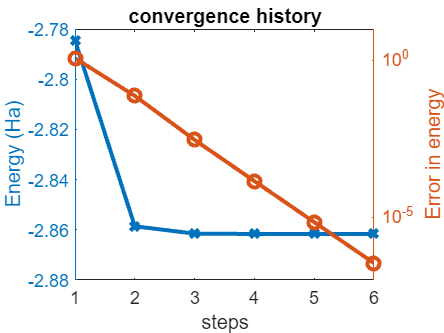

figure
yyaxis left
plot(hist_E,'-x','LineWidth',2)
ylabel("Energy (Ha)")
yyaxis right
semilogy(hist_err,'-o','LineWidth',2)
ylabel("Error in energy")
xlabel("steps")
title("convergence history")

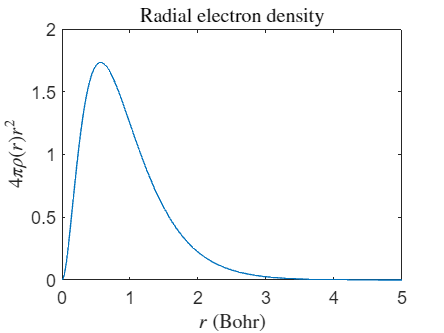

% compute electron density 
rho = calculate_rho(P,basis);
rho = subs(subs(rho,zeta1,Zeta1),zeta2,Zeta2);
figure
fplot(4*pi*r^2*rho,[0,5])
xlabel("$r$ (Bohr)",'Interpreter','latex')
ylabel("$4\pi \rho(r) r^2$",'Interpreter','latex')
xlim([0 5])
ylim([0 2])
title("Radial electron density",'Interpreter','latex')

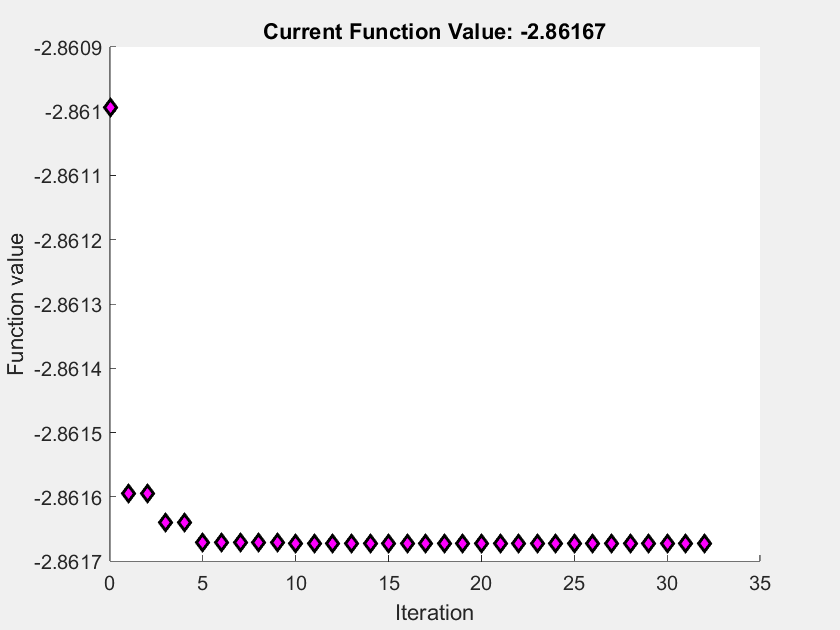

zeta_optimal =     1.4530    2.9062


% find optimal zeta1 and zeta2
F = @(z) scf(z,N,Sf,Hcoref,Rf,0);
options = optimset('PlotFcns',@optimplotfval);
zeta_optimal = fminsearch(F,[1.4,2.9],options)

## ** Exercises**

**Exercise 1:** Derive Eqs. (6) and (7) for closed-shell system described by a signle Slater determinant state for $N=4$ goven in Eq. (11).

**Exercise 2: **Show that $\sum_{m=1}^N \epsilon_{m}= \sum_{m=1}^N \int \phi^*_m (\mathbf{r} ) \hat f( \mathbf{r} ) \phi_m (\mathbf{r})d\mathbf{r} =\langle\Psi|\hat H| \Psi\rangle=E^{HF}$, where $\phi_m$ and $\epsilon_m$ are eigen functions and eigen energies of Fock operator (9).

**Exercise 3:** Apply Hartree-Fock method to describe [homogeneous electron gas](https://en.wikipedia.org/wiki/Jellium) (HEG or the jellium model). Show that plane-waves (that enter in Slater determinant) are exact single-particle eigen states for Hartree-Fock equation in the case of HEG. Show that contributions from the Hartree (direct electron-electron interaction) term and electron-positive jellium interactions cancel each other. Derive single-particle eigen energies as sum of kinetic energy (positive) and Fock exchange (negative for $|\mathbf{k}|\le k_F$) contributions: $\epsilon_{\mathbf{k}}=\frac{\mathbf{k}^2}{2}-\frac{2}{\pi}k_F F(k/k_F)$, where $F(x)= \frac{1}{2}+\frac{1-x^2}{4x}\ln{ \Big| \frac{1+x}{1-x} \Big|}$. Obtain total ground state energy of HEG in Hartree-Fock approximation, as function of $k_F$ by summing $\sum_{|\mathbf {k}|\le k_F}\epsilon (\mathbf{k})$.

## Helper Functions 

function [E,hist_E,hist_err,P] = scf(zeta,N,Sf,Hcoref,Rf,verbose)
zeta1 = zeta(1);
zeta2 = zeta(2);
Ha2eV = 27.211396641308;
Hcore = Hcoref(zeta1,zeta2);
S = Sf(zeta1,zeta2);
R = Rf(zeta1,zeta2);

[C,e] = eig(Hcore,S);
P = calculate_P(C,N);
scale = N/sum(reshape(S'.*P,[],1));
P = P*scale;
E = calculate_E(e,N,P,Hcore);
if verbose
    fprintf("Initial Energy %.6f Ha (%.6f eV)\n", E, E*Ha2eV);
end

% SCF
step = 0;
maxstep = 20;
hist_E = zeros(maxstep,1);
hist_err = zeros(maxstep,1);
err = 1;
tol = 1e-6;
E_prev = E;
while err > tol && step < maxstep
    J = calculate_J(R,P);
    K = calculate_K(R,P);
    F = Hcore + J - 0.5*K;
    [C,e] = eig(F,S);
    P = calculate_P(C,N);
    scale = N/sum(reshape(S'.*P,[],1));
    P = P*scale;
    E = calculate_E(e,N,P,Hcore);

    err = abs(E-E_prev);
    E_prev = E;
    step = step + 1;
    if verbose
        fprintf("step: %d, Energy %.6f Ha (%.6f eV), error %.2e\n", step, E, E*Ha2eV, err);
    end
    hist_E(step) = E;
    hist_err(step) = err;
end
hist_E = hist_E(1:step);
hist_err = hist_err(1:step);
end

Calculate Total energy

function E = calculate_E(e,N,P,Hcore)
e = diag(e);
E = sum(e(1:N/2));
E = E + 0.5 * sum(reshape(P.*Hcore,[],1));
end

Calculate core Hamiltonian $H_{\text{core}}$ matrix for Hartree-Fock for helium

function Hcore = calculate_Hcore(basis)
nbasis = length(basis);
syms r theta phi real 
syms Hcore [nbasis nbasis] matrix

for i = 1:nbasis
    bi = basis(i);
    Hbi = -0.5* diff((r^2*diff(bi,r)),r)/r^2 - 2/r*bi;
    for j = 1:nbasis
        bj = basis(j);
        temp = int(int(int(bj*(Hbi)*r^2*sin(theta),r,0,inf),theta,0,pi),phi,0,2*pi);
        Hcore(i,j) = temp;
        if j ~= i
            Hcore(j,i) = temp;
        end
    end
end
end

Calculate Coulomb matrix J for Hartree-Fock for helium


$$J_{ij} = \sum_{mn} P_{mn}\left(im\left|r_{12}^{-1}\right| jn\right)$$


function J = calculate_J(R,P)
nbasis = size(R,1);
J = zeros(nbasis);
for i = 1:nbasis
    for j = 1:nbasis
        for m = 1:nbasis
            for n = 1:nbasis
                J(i,j) = J(i,j) + P(m,n)*R(i,m,j,n);
            end
        end
    end
end
end

Calculate exchange matrix K for Hartree-Fock for helium


$$K_{ij} = \sum_{mn} P_{mn}\left(im\left|r_{12}^{-1}\right| nj\right)$$


function K = calculate_K(R,P)
nbasis = size(R,1);
K = zeros(nbasis);
for i = 1:nbasis
    for j = 1:nbasis
        for m = 1:nbasis
            for n = 1:nbasis
                K(i,j) = K(i,j) + P(m,n)*R(i,m,n,j);
            end
        end
    end
end
end

Calculate density matrix P for Hartree-Fock for helium using Eq. (19)

function P = calculate_P(C,N)
assert(N==2);
nbasis = size(C,1);
P = zeros(nbasis);
for l = 1:nbasis
    for s = 1:nbasis
        for t = 1:N/2
            P(l,s) = P(l,s) + 2*C(l,t)*C(s,t);
        end
    end
end
end

Calculate all four-center integral and store in R


$$\left(im\left|r_{12}^{-1}\right| jn\right)=\int  \phi_i^*\left(\mathbf{r}_1\right) \phi_m^*\left(\mathbf{r}_2\right) \frac{1}{r_{12}} \phi_j\left(\mathbf{r}_1\right) \phi_n\left(\mathbf{r}_2\right) \,d \mathbf{r}_1 d \mathbf{r}_2\qquad (24)$$


function R = calculate_R(basis)
nbasis = length(basis);
R = sym('R', [nbasis nbasis nbasis nbasis]);
for i = 1:nbasis
    for j = 1:nbasis
        for m = 1:nbasis
            for n = 1:nbasis
                R(i,m,j,n) = fcintegral(basis,i,m,j,n);
            end
        end
    end
end
end

When using spherically symmetric orbitals, the four-center integral is analytically doable. Using the [Laplace expansion](https://en.wikipedia.org/wiki/Laplace_expansion_(potential)) of the inverse distance we have 

$\frac{1}{r_{12}}=\sum_{l=0}^{\infty} \sum_{m=-l}^l \frac{4 \pi}{2 l+1} \frac{r_{<}^l}{r_{>}^{l+1}}\left[Y_l^m\left(\theta_1, \phi_1\right)\right]^* Y_l^m\left(\theta_2, \phi_2\right)$,

where $r_{<}$ means the smaller of $r_1$ and $r_2$, and $r_{>}$ is the larger of $r_1$ and $r_2$. We substitute this expansion of inverse distance into the integral (67). Then we multiply the right side by $Y_0^0\left(\theta_1, \phi_1\right)\left[Y_0^0\left(\theta_2, \phi_2\right)\right]^*(4 \pi)$ (which equals 1) and integrate over angular variables. Using the orthonormality of the spherical harmonics to evaluate the angular integrals in terms of Kronecker deltas, we obtain: 

$\left(im\left|r_{12}^{-1}\right| jn\right)=(4\pi)^2 \int  \int \phi^*_i(r_1) \phi^*_m(r_2) \frac{1}{r_>} \phi_j(r_1) \phi_n(r_2) dr_1 dr_2$.

function intJ= fcintegral(basis,i,m,j,n)
bi = basis(i);
bm = basis(m);
bj = basis(j);
bn = basis(n);

syms r r1 r2 real 
bi = subs(bi,r,r1);
bm = subs(bm,r,r2);
bj = subs(bj,r,r1);
bn = subs(bn,r,r2);

p = (4*sym(pi))^2*bi*bm*bj*bn;
intJ = int(int(p/r2*r1^2*r2^2,r1,0,r2),r2,0,inf) + int(int(p/r1*r1^2*r2^2,r1,r2,inf),r2,0,inf);
end

Calculate overlap matrix $S$ for Hartree-Fock for helium

function S = calculate_S(basis)
nbasis = length(basis);
syms S [nbasis nbasis] matrix %symbolic matrix variable

syms r theta phi real 
for i = 1:nbasis
    bi = basis(i);
    for j = i:nbasis
        bj = basis(j);
        temp = int(int(int(bj*(bi)*r^2*sin(theta),r,0,inf),theta,0,pi),phi,0,2*pi);
        S(i,j) = temp;
        if j ~= i
            S(j,i) = temp;
        end
    end
end
end

Calculate electron density using density matrix $P$ and basis set. 

function rho = calculate_rho(P,basis)
nbasis = length(basis);
rho = 0;
for i = 1:nbasis
    for j = 1:nbasis
        rho = rho + P(i,j)*basis(i)*basis(j);
    end
end
end

## References

1. [https://web.stanford.edu/~kimth/www-mit/thk_hartreefock.pdf](https://web.stanford.edu/~kimth/www-mit/thk_hartreefock.pdf) 